# Transducer Design

Transducer 1

% Define common properties
clc; close; clear;
transducer_info = [];
transducer_info.Frequency = 40000;        % 40kHz (operating frequency of transducer)
% transducer_info.Pressure = 36.3477;   % Surface outcome pressure [Pa]
transducer_info.Pressure = 1;  
transducer_info.Type = 'circle';
transducer_info.Radius = 0.005;      
transducer_info.medium = 'air';

% Positions and phases for the transducers (1 row)
positions = [];
for k = 1:8
    positions(k) = 0.005 + 0.01 * (k-1);
end

% PFC_PhaseCalculate_for16(target[x,y], array, focal point z(m))
% phases = PFC_PhaseCalculate_for16([0.04, 0.04], [8,8], 0.1)
phases = PFC_PhaseCalculate([0.04, 0.04], [8,8], 0.02)

phases =    39.1172   34.7566   31.5160   29.7638   29.7638   31.5160   34.7566   39.1172
   34.7566   29.7638   25.9060   23.7433   23.7433   25.9060   29.7638   34.7566
   31.5160   25.9060   21.3627   18.6811   18.6811   21.3627   25.9060   31.5160
   29.7638   23.7433   18.6811   15.5436   15.5436   18.6811   23.7433   29.7638
   29.7638   23.7433   18.6811   15.5436   15.5436   18.6811   23.7433   29.7638
   31.5160   25.9060   21.3627   18.6811   18.6811   21.3627   25.9060   31.5160
   34.7566   29.7638   25.9060   23.7433   23.7433   25.9060   29.7638   34.7566
   39.1172   34.7566   31.5160   29.7638   29.7638   31.5160   34.7566   39.1172


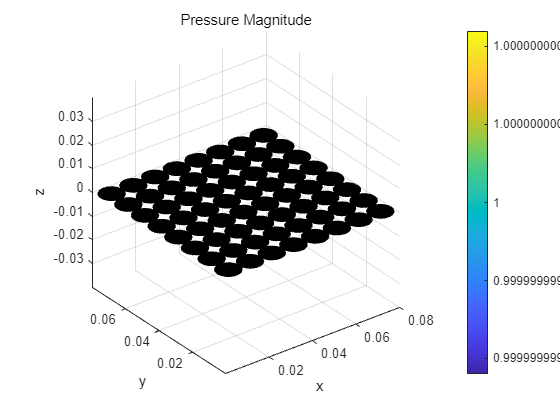

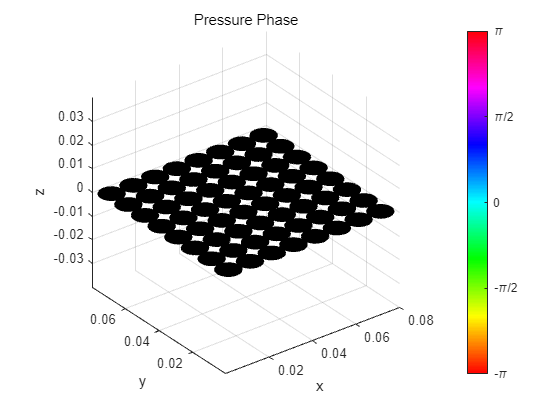

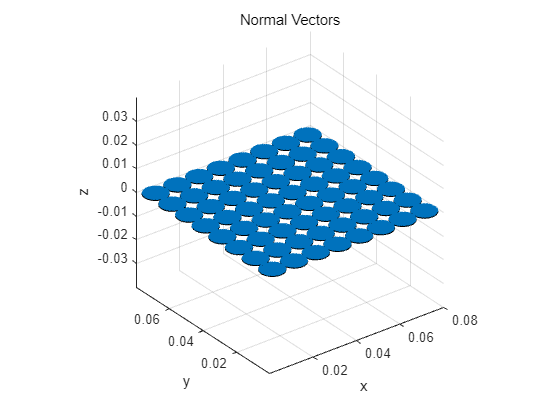


% Counter for linear indexing into transducer_object
index = 1;

% Populate the transducer objects
for i = 1:8
    for j = 1:8
        % Update position and phase
        transducer_info.position = [positions(j), positions(i), 0];

        transducer_info.Phase = -phases(i,j);
        % transducer_info.Phase = 0;
        transducer_object(index) = PFC_Make3DTransducer(transducer_info);

        % Increment index for next transducer
        index = index + 1;
    end
end

% Draw all transducers in 3D once
PFC_DrawTransducer3D(transducer_object, '-');

## Frequency Domain

input_source.Type = 'frequency';
input_source.reading_list = 40000; % [Hz]

## Simulation Space

reading_pos_x = 0e-3 : 0.5e-3 : 80e-3;          % Simulation Area
reading_pos_y = 0e-3 : 0.5e-3 : 80e-3;          % Simulation Area
reading_pos_z = 0e-3 : 0.5e-3 : 80e-3;          % Simulation Area

## Run Frequency Domain Simulation

XZ Plane

% xz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, 0.04, reading_pos_z);

Started at 2024-10-11 20:21:19
Finished at 2024-10-11 20:22:07
Progressed time : 00:00:48


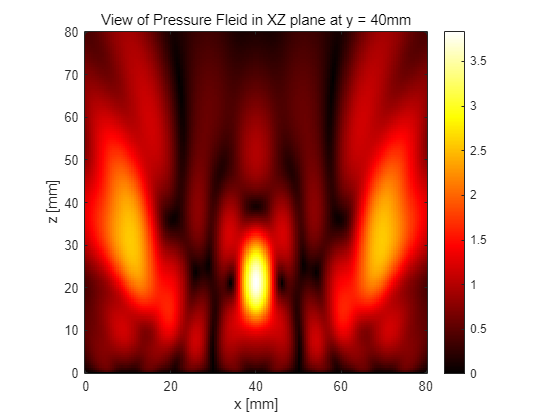


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));
Pressure_dxyz_i_rot = rot90(Pressure_dxyz_i, -1);

figure;imagesc(reading_pos_x.*1e3, reading_pos_z.*1e3, Pressure_dxyz_i_rot);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top', 'YDir', 'normal');
title('View of Pressure Fleid in XZ plane at y = 40mm');
colorbar;
colormap(hot);
xlabel('x [mm]');
ylabel('z [mm]');

M1 = max(Pressure_dxyz_i,[],"all")

M1 = 3.8405

% row_data = Pressure_dxyz_i(49, :);
% plot(row_data);
% xlabel('Z-index');
% ylabel('Gain');
% title('Gain graph at Center');
% grid on;

XY Plane

% xy plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, reading_pos_y, 0.02);

Started at 2024-10-11 20:22:08
Finished at 2024-10-11 20:22:48
Progressed time : 00:00:40


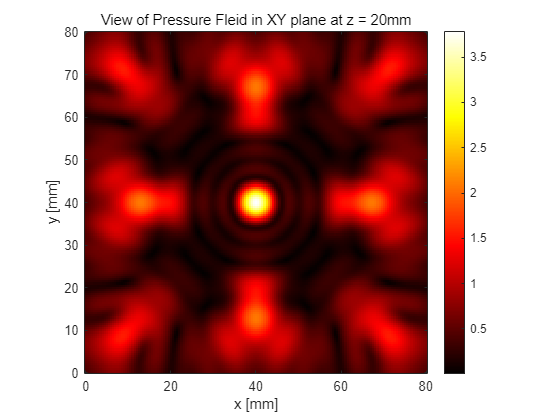


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top','YDir', 'normal');
title('View of Pressure Fleid in XY plane at z = 20mm');
colorbar;
colormap(hot);
xlabel('x [mm]');
ylabel('y [mm]');